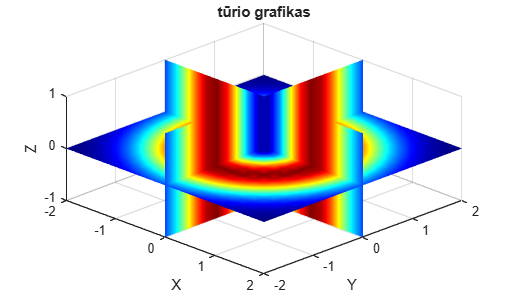

%Gustas Neverdauskas EAf-25 LAB4

clear all;

figure;


x = linspace(-2, 2, 20);
y = linspace(-2, 2, 20);
z = linspace(-1, 1, 20);
[X, Y, Z] = meshgrid(x, y, z);

V = sin((X.^2 + Y.^2) / 20) .* exp(-(X.^2 + Y.^2));
slice(X, Y, Z, V, 0, 0, 0);

colormap('jet');      
shading interp;     
view(45, 45);          
grid on;

title('tūrio grafikas');
xlabel('X');
ylabel('Y');
zlabel('Z');

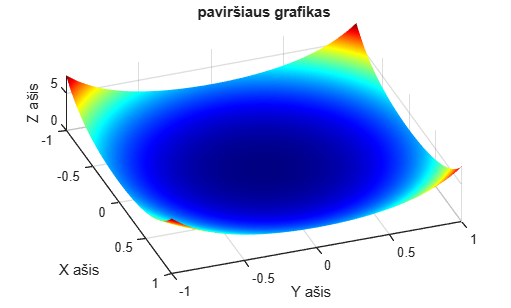

clear all;
%2grafikas

figure;

x = linspace(-1, 1, 100);
y = linspace(-1, 1, 100);
[X, Y] = meshgrid(x, y);

R = sqrt(X.^2 + Y.^2);
Z = exp(R.^2);
surf(X, Y, Z);

colormap('jet');      
shading interp;        
view(70, 70);  
grid on;

title('paviršiaus grafikas');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');

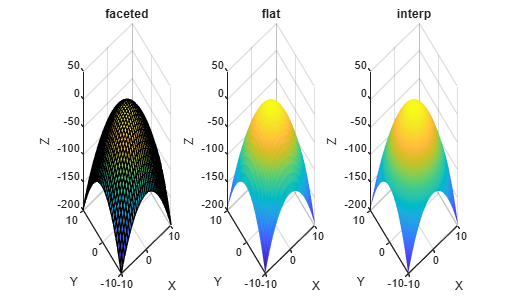

%Papildoma

clear all;

figure;

x = linspace(-10, 10, 30);
y = linspace(-10, 10, 30);
[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

%su faceted
subplot(1, 3, 1);
surf(X, Y, Z);
shading faceted;
title('faceted');
xlabel('X');
ylabel('Y'); 
zlabel('Z');
grid on;

%su flat
subplot(1, 3, 2);
surf(X, Y, Z);
shading flat;
title('flat');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;

%su interp
subplot(1, 3, 3);
surf(X, Y, Z);
shading interp;
title('interp');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;